# “Ψηφιακή Επεξεργασία και Ανάλυση Εικόνας” Ακαδημαϊκό Έτος 2020-21 (Εαρινό Εξάμηνο) Εργαστηριακές Ασκήσεις - Μέρος Α΄ 

## ΟΝΟΜΑΤΕΠΩΝΥΜΟ : ΤΣΑΚΤΑΝΗΣ ΓΕΩΡΓΙΟΣ

## ΑΜ : 1059343

## ΤΜΗΜΑ : ΗΜΤΥ

## ΕΤΟΣ : 4ο

### **Ασκηση 1. Φιλτράρισμα στο πεδίο συχνοτήτων**

### **1)ΠΡΟΕΠΕΞΕΡΓΑΣΙΑ **

αφου φορτωθεί η εικόνα ως πίνακας x παρατηρείται ότι δεν καλύπτει τελείως της δυναμική περιοχή 0,255 οπότε εφαρμόζουμε γραμμικό μετασχηματισμό, δηλαδή βρίσκουμε το ελάχιστο του πίνακα χ και το μέγιστο και τα τοποθετούμε στον τύπο 

**255*(x-minimum) / (maximum-minimum) .  **Αφού πετύγχουμε τον γραμμικό μετασχηματισμό εμφανιζουμε τα ιστογράμματα και παρατηρείται η διαφορά. Μια παρατήρηση ώστε να καλύπτεται ακόμα περισσότερο η δυναμική περιοχή είναι να θεωρηθεί minimum μία τιμή κοντά στο 70 αφού τα  pixel παίρνουν τιμές κυρίως από 50 εώς 248 πέρα από κάποιες ελάχιστες που φτάνουν και εώς το 1.

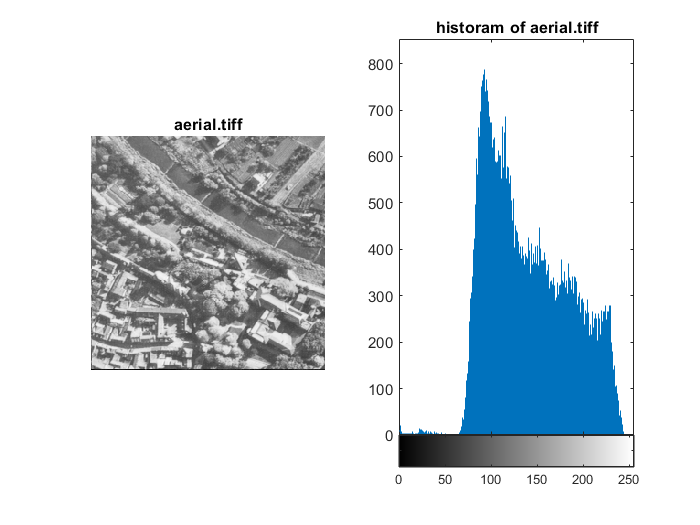

clc
clear all

x= imread('images\1\aerial.tiff');
[rows,cols]=size(x);
minValue= min(x(:));
maxValue = max(x(:));


x_linear=255*(double(x)-double(minValue))/double((maxValue-minValue));
minValue_alter=50;
x_linear_alter=255*(double(x)-double(minValue_alter))/double((maxValue-minValue_alter));
figure()
subplot(1,2,1)
imshow(x,[0,255]);
title("aerial.tiff")
subplot(1,2,2)
imhist(x)
title("historam of aerial.tiff");

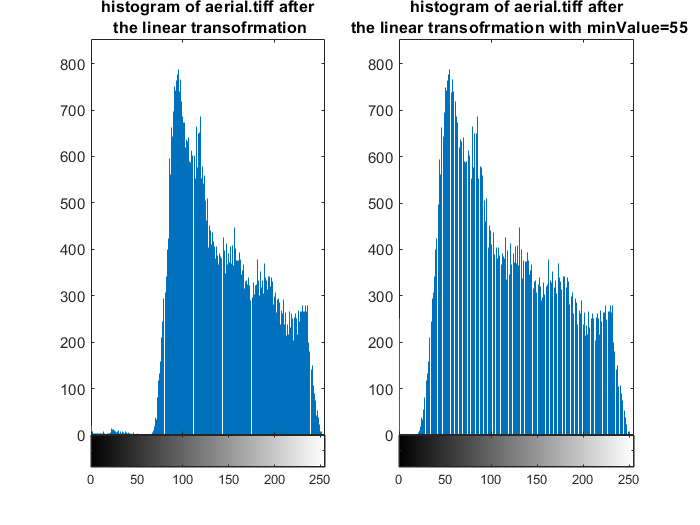

figure()
subplot(1,2,1)
imhist(uint8(x_linear))
title({"histogram of aerial.tiff after" ; " the linear transofrmation"})
subplot(1,2,2)
imhist(uint8(x_linear_alter))
title({"histogram of aerial.tiff after" ; " the linear transofrmation with minValue=55"})

**2)**Εφαρμόζοντας δισδιάστατο διακριτό μετασχηματισμό Fourier με τη μέθοδο γραμμών-στηλών και χρησιμοποιώντας το μονοδιάστατο μετασχηματισμό DFT .'Οπου X_gram_shifted και X_log είναι η γραμμική και λογαριθμηκή απεικόνιση. Για να μεταφερθεί  το συχνοτικό σημείο (0,0) στο κέντρο του πεδίου χρησιμοποιείται η έτοιμη εντολή της matlab** fftshift() **αφού πρώτα περάσουμε στο πεδίο της συχνότητας**.**

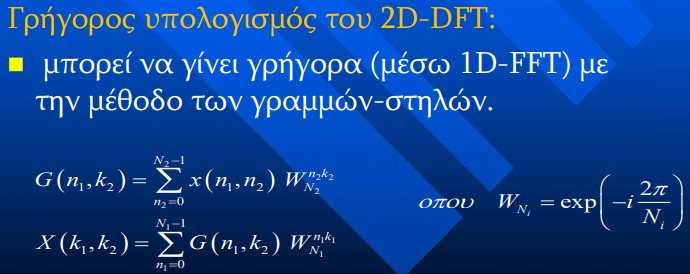

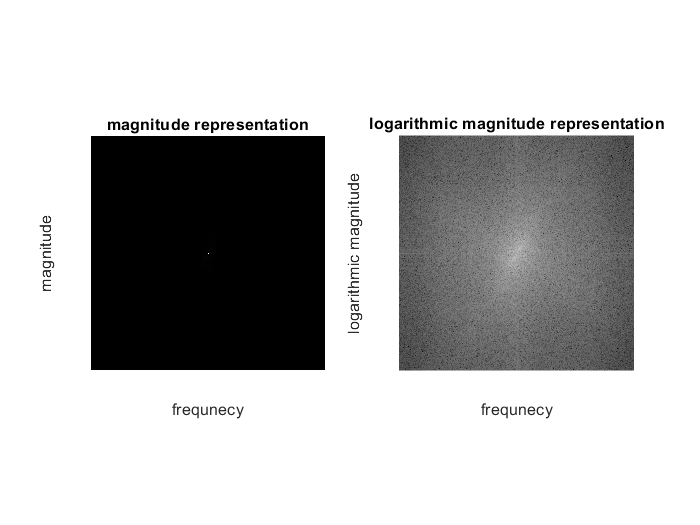


G=fftshift(fft(x, [], 1),1);%fft to the rows of x due to dim=1 and applies the fftshift 
% operation along the dimension 1 ---> rows.
X_2dfft=fftshift(fft(G, [], 2),2); %fft to the columns of G due to dim=2 and applies the fftshift 
% operation along the dimension 2 ---> columns.
X_2dfft_abs=abs(X_2dfft);
min1=min(X_2dfft_abs,[],'all');
max1=max(X_2dfft_abs,[],'all');
logX_2dfft=abs(log(X_2dfft_abs));
min2=min(logX_2dfft,[],'all');
max2=max(logX_2dfft,[],'all');
figure()

subplot(1,2,1)
imshow(X_2dfft_abs,[min1,max1])
title('magnitude representation')
xlabel('frequnecy')
ylabel('magnitude')
subplot(1,2,2)
imshow(logX_2dfft,[min2,max2])
title('logarithmic magnitude representation')
xlabel('frequnecy')
ylabel('logarithmic magnitude')

figure()

**3) Κώδικας για 2D χαμηλοπερατό φίλτρο  **

**a,b είναι δυο πίνακες συχνοτήτων με τιμές περίπου απο το -1 στο 1 'οπου οι γραμμές του α αντιστοιχούν στις στήλες του b και με τον τύπο  **$d=\sqrt{\alpha^2 +\beta^2 }$**  στοιχείο προς στοιχείο και αν d < =1 τότε η συνάρτηση μεταφοράς του κατωπερατού φίλτρου γίνεται 1 αλλιώς γίνεται 0. Πηγή mathworks .**

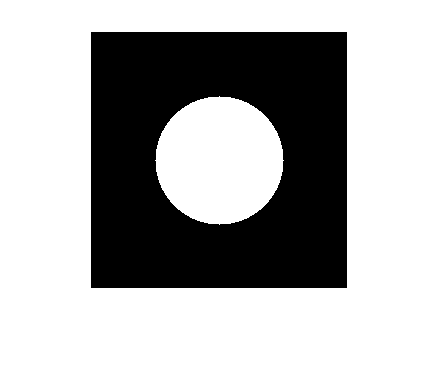

% Matlab Program for 2D Low Pass Filter
[a,b] = freqspace(256,'meshgrid');
d = zeros(256,256);
for i = 1:256
    for j = 1:256
        d(i,j) = sqrt(a(i,j).^2 + b(i,j).^2);
    end
end
c = 0.5;
H = zeros(256,256);
for i = 1:256
    for j = 1:256
        if abs(d(i,j)) <= 0.5
            H(i,j) = 1;
        else
            H(i,j) = 0;
        end
    end
end
imshow(H);

4-5) Αφού γίνει πολλαπλασιασμός στο πεδίο της συχνότητας ανάμεσα στο φίλτρο και στο fourier της εικόνας προκύπτει το Y_filtered. Για να επαναφέρουμε το 2d σήμα στο πεδίο του χρόνου κάνουμε 2 φορές ανάποδο 1d ταχύ μετασχηματισμό fourier που αντιστοιχεί σε 1d IDFT , ταυτόχρονα μεταφέρουμε- αναιρουμε το fft shift και πλοτάρουμε το μέτρο του σήματος x_filtered.

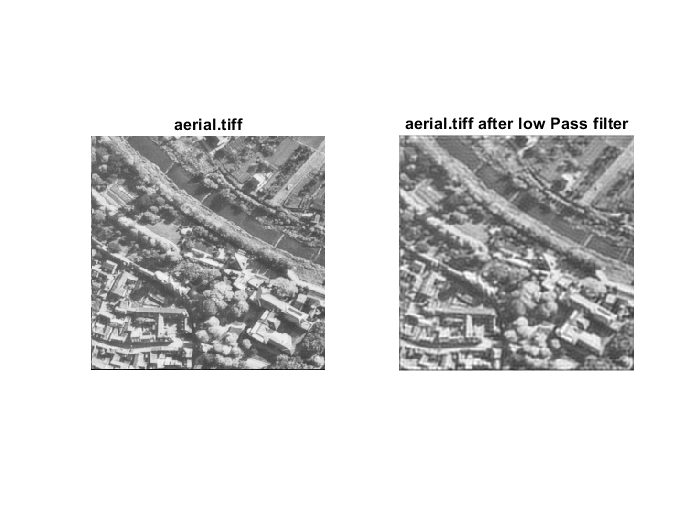

Y_filtered=X_2dfft.*H;
G_new=ifft(ifftshift(Y_filtered, 1), [],1);
x_filtered=ifft(ifftshift(G_new, 2), [],2);
x_filtered=abs(x_filtered);
figure()
subplot(1,2,1);
imshow(x,[0,255]);
title("aerial.tiff");
subplot(1,2,2);
imshow(x_filtered,[0,255]);
title("aerial.tiff after low Pass filter");

Παρατηρείται ότι η εικόνα που προέκυψε έπειτα από φιλτράριμσα Low pass filter είναι πιο θολή και αυτό οφείλεται στο ότι εχουν περικοπέι υψηλές συχνότητες που καθιστούν πιο ευδιάκριτες λεπτομέριες σε γραμμές και μεταβάσεις σχημάτων.